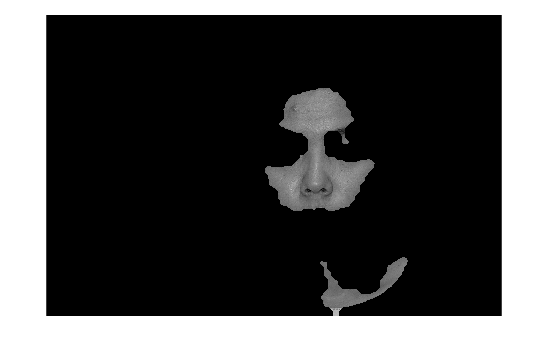

% Denna fil är för tnm034.m, bör användas av den
% tnm034 tar in en im, skickar ut ID av identifierad person.
% funkar när facemask appliceras korrekt, den gör ej på 5, 6, 11?
% senase versionen funkar alla
clear
im = imread("images/DB2/il_16.jpg");
im = im2double(im); % konvertera till double pga faceMask funktionen kräver det

% applicera facemask
facemask = skinDetection(im);
im = im.*facemask;

% vitbalans test
im = AWB_max(im); % den här verkar inte göra nåt?

%%%%%%%%%%%% Följer Eye Detection artikeln av bl.a Tanmay Rajpathak
%%%%%%%%%%%% omskalning kommer fucka upp algoritmen, vinkeländring borde ha bra tolerans
%%%%%%%%%%%% TODO: kolla om det är ok att ta bort 1/2 vertikalen 

% konvertera bilden till NTSC format för att enklare hitta eye dot, detta är YIQ färgrymd 
% använd endast chromasity kanalen
YIQim = rgb2ntsc(im);
imChrom = YIQim(:,:,1);
imshow(imChrom);

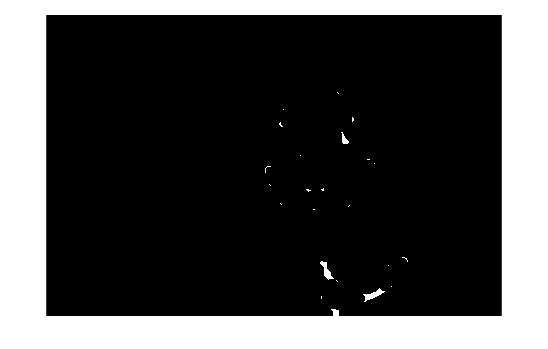


% bilddimensioner, används för att normalisera distanser för bilderna
im_height = length(imChrom(:,1)); im_width = length(imChrom(1,:));
im_area = im_height*im_width;
im_dist = round(sqrt(im_area));

% morfologi, dilation följt av erosion med 9x9 element och tar differensen
% chromasity kanalen är double så det funkar
% inget blir över 1 då vi tar differens, värden under 0 irrelevanta
se1 = strel('disk', 9); % värde från artikel
imOp = imopen(imChrom,se1);
imCl = imclose(imChrom,se1);
imDiff = imCl - imOp;

% Adaptiv tröskla genom bilden tills 6 blobbar med min area eller 2 med max area
thresh = 0.8; step = 0.05;
blob_minarea = round(im_area/10000); blobs_maxarea = round(im_area/1000); % valde på känsla (skalning kommer fucka)
counter_minarea = 0; counter_maxarea = 0;

imThresh = imDiff(:,:) > thresh;
blobs = regionprops(imThresh);
blobs_amount = length(blobs(:)); % det här värdet används alltid

while counter_minarea < 7 && counter_maxarea < 2 && thresh > 0.35
    counter_minarea = 0; counter_maxarea = 0;
    thresh = thresh - step;
    imThresh = imDiff(:,:) > thresh;
    blobs = regionprops(imThresh);
    blobs_amount = length(blobs(:));
    for i = 1:1:blobs_amount
        if blobs(i).Area > blob_minarea
            counter_minarea = counter_minarea + 1;
            if blobs(i).Area > blobs_maxarea
                counter_maxarea = counter_maxarea + 1;
            end
        end
    end
end
imshow(imThresh);

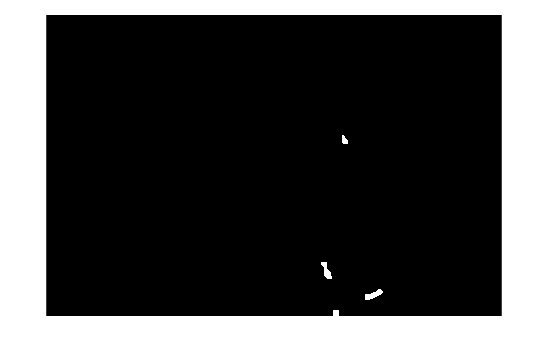


% Gör ögon tydligare, ta bort noise genom morfologisk stängning
se2 = strel('disk',3); % värde från artikeln
imThresh = imopen(imThresh,se2);
imThresh = imclose(imThresh,se2);
imshow(imThresh);

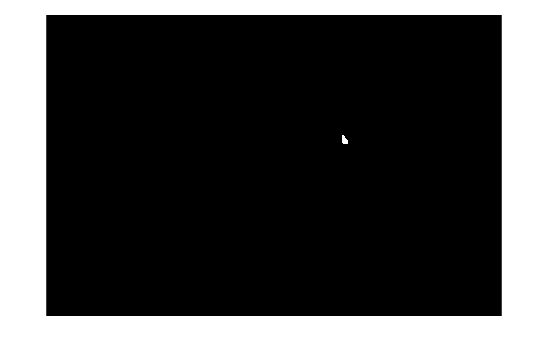


% ta bort blobbar från kanten som är 1/4 över under, är för långa
% Omringar området som tas bort med en låda vilket kan överlappa ögats blob
maxLength = im_dist/6;
h_remove = round(im_height/4);
blobs = regionprops(imThresh);
blobs_amount = length(blobs(:));

if blobs_amount > 2
    for i = 1:1:blobs_amount
        box = blobs(i).BoundingBox;
        if blobs(i).Centroid(2) < h_remove || blobs(i).Centroid(2) > im_height - h_remove || box(3) > maxLength || box(4) > maxLength
            imThresh(round(box(2)):round(box(4) + box(2)-1), round(box(1)):round(box(3) + box(1)-1)) = 0;
        end
    end
end
imshow(imThresh);


% Testar varje blobb mot varandra. Om längre än 1/3.5 av bild +- samt +-15 grader, ta bort
% TODO: distans behöver stor tolerans för svåra bilder
optDist = round(im_dist/3.5); tol = round(optDist/5); % valde dessa på känsla (skalning kommer fucka)
blobs = regionprops(imThresh);
blobs_amount = length(blobs(:));
blob_current = 1;
while blob_current < blobs_amount + 1 && blobs_amount > 2
    blob_candidate = false;
    for i = 1:blobs_amount
        % sqrt((x1-x2)^2+(y1-y2)^2)
        % asin(motstående katet/hypotenusa) = vinkel i radianer
        hypotenuse = sqrt((blobs(blob_current).Centroid(1) - blobs(i).Centroid(1))^2 + (blobs(blob_current).Centroid(2) - blobs(i).Centroid(2))^2);
        perpendicular = abs(blobs(blob_current).Centroid(2) - blobs(i).Centroid(2));
        angle = asin(perpendicular/hypotenuse);
        % disp(angle);
        if i ~= blob_current && abs(optDist - hypotenuse) < tol && angle < 0.26 % är detta rätt?
            blob_candidate = true;
        end
    end
    if blob_candidate == false
        box = blobs(blob_current).BoundingBox;
        imThresh(round(box(2)):round(box(4) + box(2)-1), round(box(1)):round(box(3) + box(1)-1)) = 0;
    end
    blob_current = blob_current + 1;
end
imshow(imThresh);


% Få ögats position med regionprops, markera med insertMarker
eyeStruct = regionprops(imThresh);
eyes_amount = length(eyeStruct(:));
if eyes_amount == 2
    eye1 = eyeStruct(1).Centroid;
    eye2 = eyeStruct(2).Centroid;
else
    eye1 = zeros(1,2);
    eye2 = zeros(1,2);
    disp("ERROR: Could not find the eyes, try increasing/decreasing the threshold value");
end

ERROR: Could not find the eyes, try increasing/decreasing the threshold value


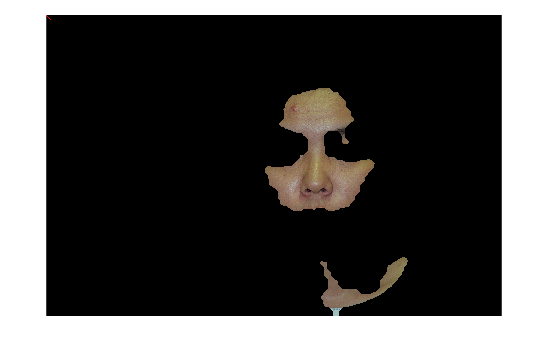

pos = [eye1; eye2];
im = insertMarker(im, pos, 'star','color','red','size',10);
imshow(im);